# Assignment 2 Deep Learning Approach

Credits to Najini for her code.

## Load and Explore Image Data

Load the digit sample data as an image datastore. `imageDatastore` automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore enables you to store large image data, including data that does not fit in memory, and efficiently read batches of images during training of a convolutional neural network.

%CIFAR10
rootFolder = 'cifar10Train';
categories = {'airplane','automobile','bird','cat','deer','dog','frog','horse','ship','truck'};
numTrainFiles = 4500;

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');

Count the total number of different classes

labelCount = countEachLabel(imds)

labelCount = 10×2 table
      Label       Count
    __________    _____

    airplane      5000 
    automobile    5000 
    bird          5000 
    cat           5000 
    deer          5000 
    dog           5000 
    frog          5000 
    horse         5000 
    ship          5000 
    truck         5000 


## Specify Training and Validation Sets

Divide the data into training and validation data sets, so that each category in the training set contains 750 images, and the validation set contains the remaining images from each label. `splitEachLabel` splits the datastore `digitData` into two new datastores, `trainDigitData` and `valDigitData`.

[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## Define Network Architecture

Define the convolutional neural network architecture.

layers = [
    imageInputLayer([32 32 3])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer

    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

## Specify Training Options

Tune the hyperparameters of the training, we decided to use a larger number of epochs to ensure convergence.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',6, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train Network Using Training Data

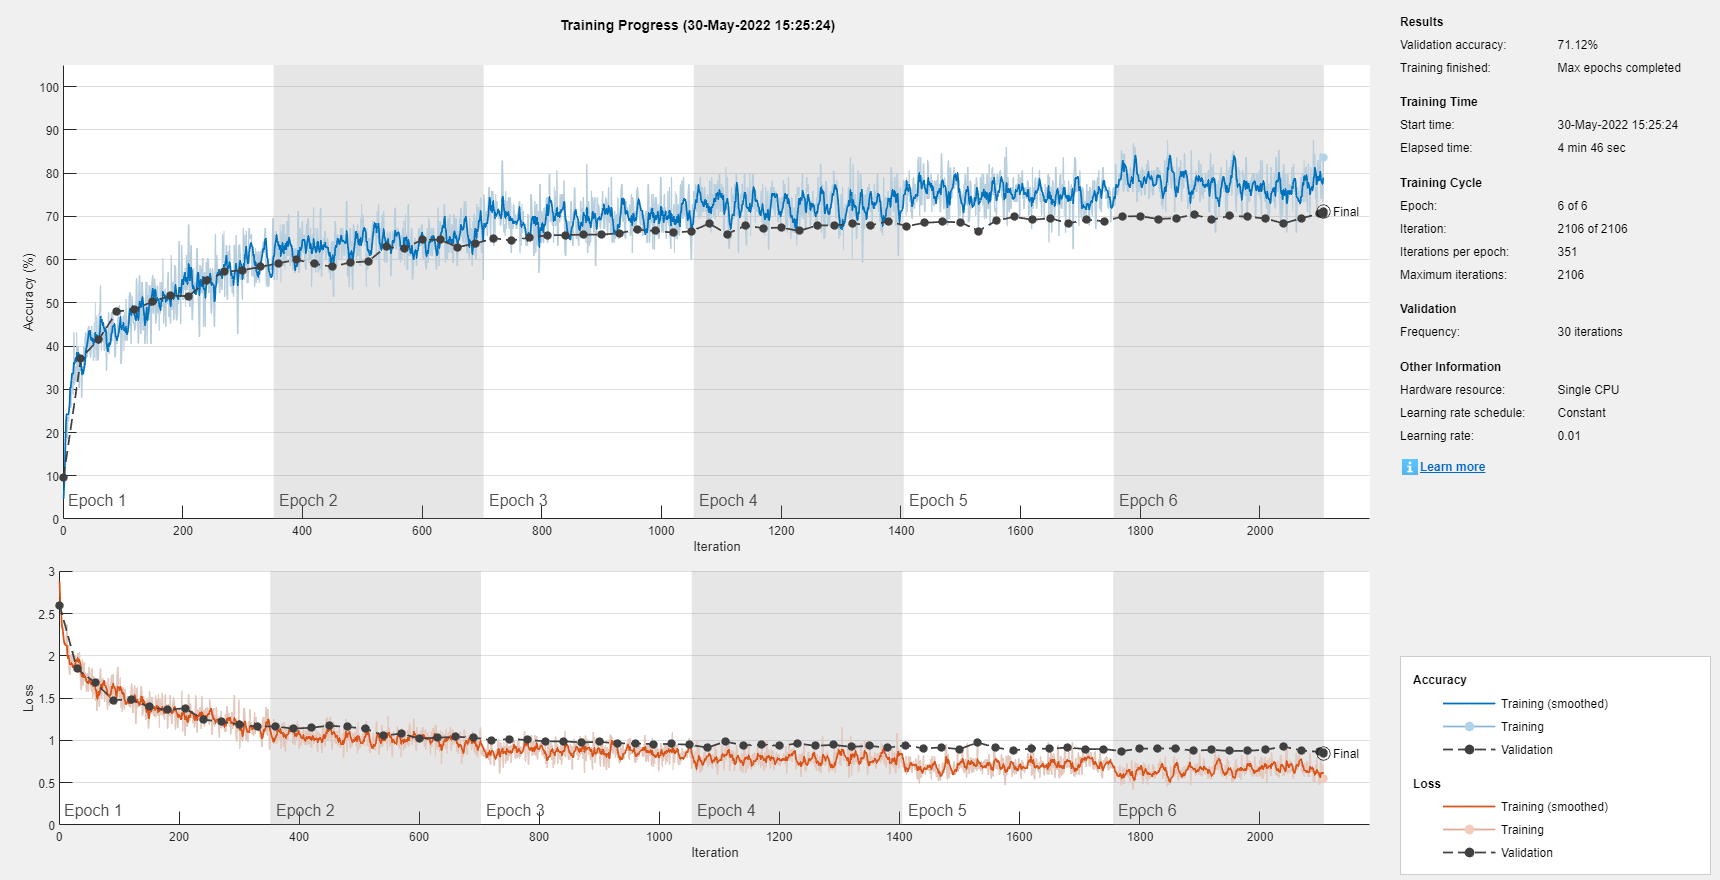

net = trainNetwork(imdsTrain,layers,options);

## Classify Validation Images and Compute Accuracy

Predict the labels of the validation data using the trained network, and calculate the final validation accuracy. Accuracy is the fraction of labels that the network predicts correctly. 

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.7112

*Copyright 2018 The MathWorks, Inc.*

rootFolder = 'cifar10test';
categories = {'airplane','automobile','bird','cat','deer','dog','frog','horse','ship','truck'};
imdsTEST = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');

YTest = classify(net,imdsTEST);

% Tabulate the results using a confusion matrix.
confMat10 = confusionmat(imdsTEST.Labels, YTest)

confMat10 =    689    12    38    18    34     7     8    11   130    53
    16   790     9    10     4     4    10     6    27   124
    62     8   596    62    89    56    53    43    20    11
    23    11    68   529    72   131    61    55    17    33
    21     3    64    64   701    30    37    62     9     9
    15     3    43   183    60   562    28    73    16    17
     4     6    50    66    56    19   758    18    14     9
    10     0    24    42    60    31     9   797     5    22
    46    30     8    11     7     3     2    11   852    30
    28    58     8    14    11    11     5    18    28   819
